# MATLAB Föreläsning 9

## Undersök riktningsfält 

Betrakta ODE 


$$y'(t) = f(t,y) $$


Högerledet i ekvationen ger tangentens riktning för lösningen $y(t)$. 

Plotta analytiska lösningar till $y' = y$ med $y(0) = c$. Lösningar till ekvationen är $y(t) = ce^t$.

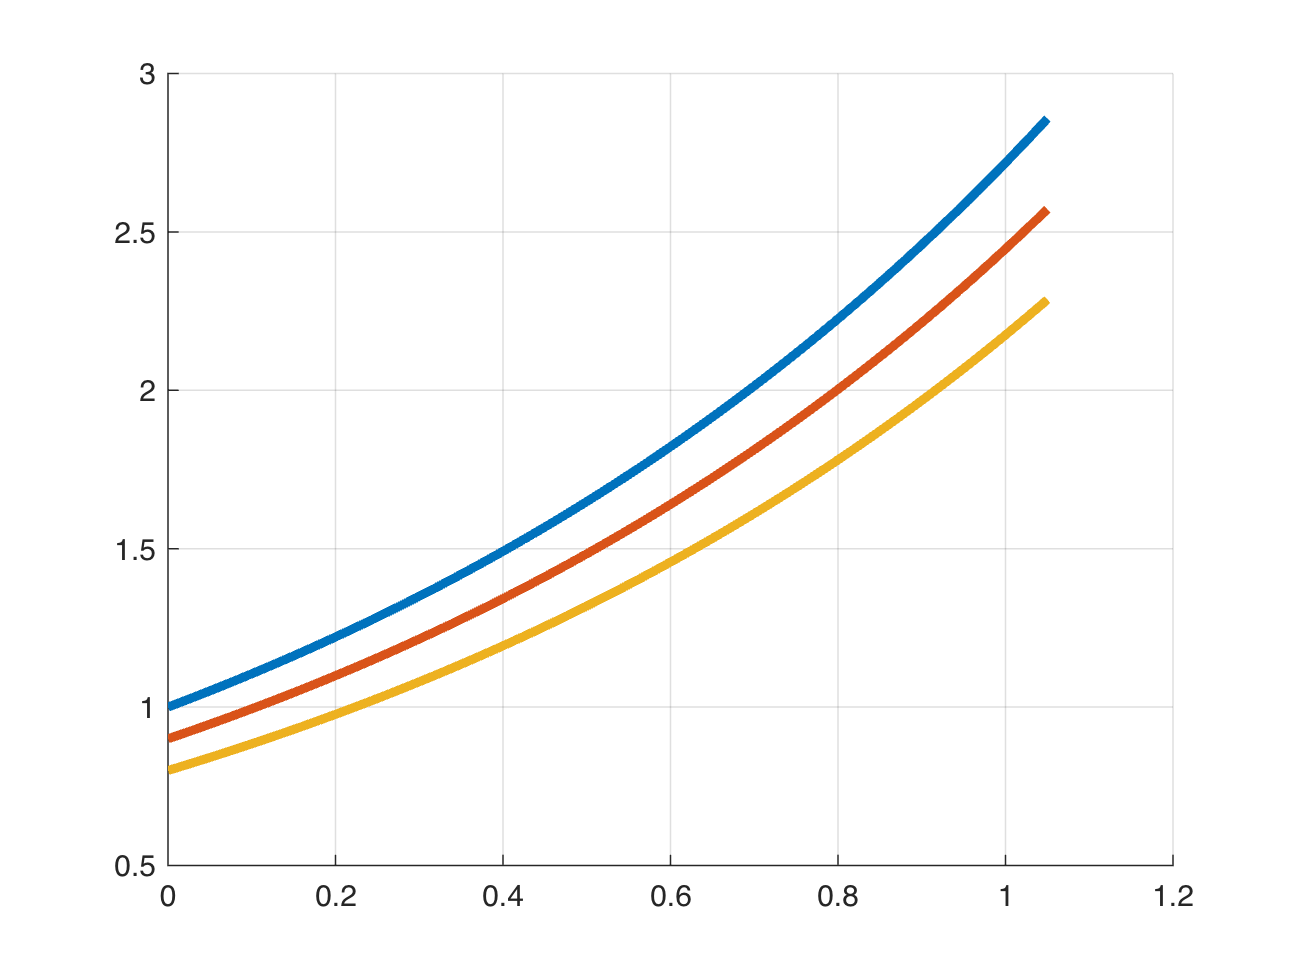

clear
t = linspace(0,1.05,100);

% Välj tre olika begynnelsevillkor:
c1 = 1;
c2 = 0.9;
c3 = 0.8;

y1 = c1*exp(t);
y2 = c2*exp(t);
y3 = c3*exp(t);

clf
hold on 
plot(t,y1,'LineWidth',3)
grid on
plot(t,y2,'LineWidth',3)
plot(t,y3,'LineWidth',3)
ylim([0.5,3])

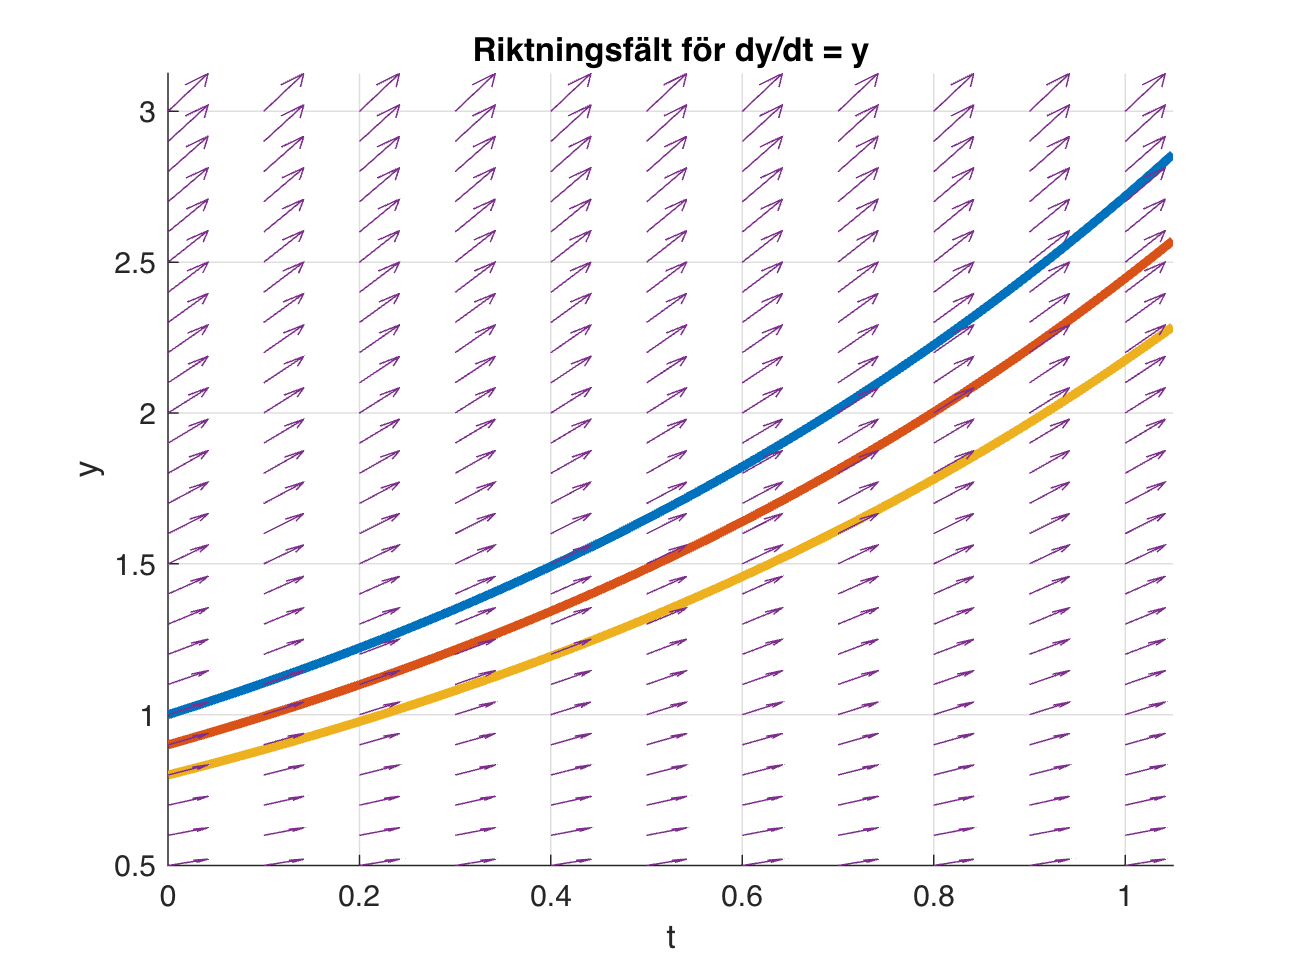

clf
hold on 
plot(t,y1,'LineWidth',3)

grid on
plot(t,y2,'LineWidth',3)
plot(t,y3,'LineWidth',3)
ylim([0.5,3])

[T, Y] = meshgrid(0:0.1:1, 0.5:0.1:3);
%S = -T+ Y + 1./Y-T;
S = Y;
quiver(T, Y, ones(size(S)), S,1)
axis tight; xlabel('t'), ylabel('y')
title('Riktningsfält för dy/dt = y')
hold off

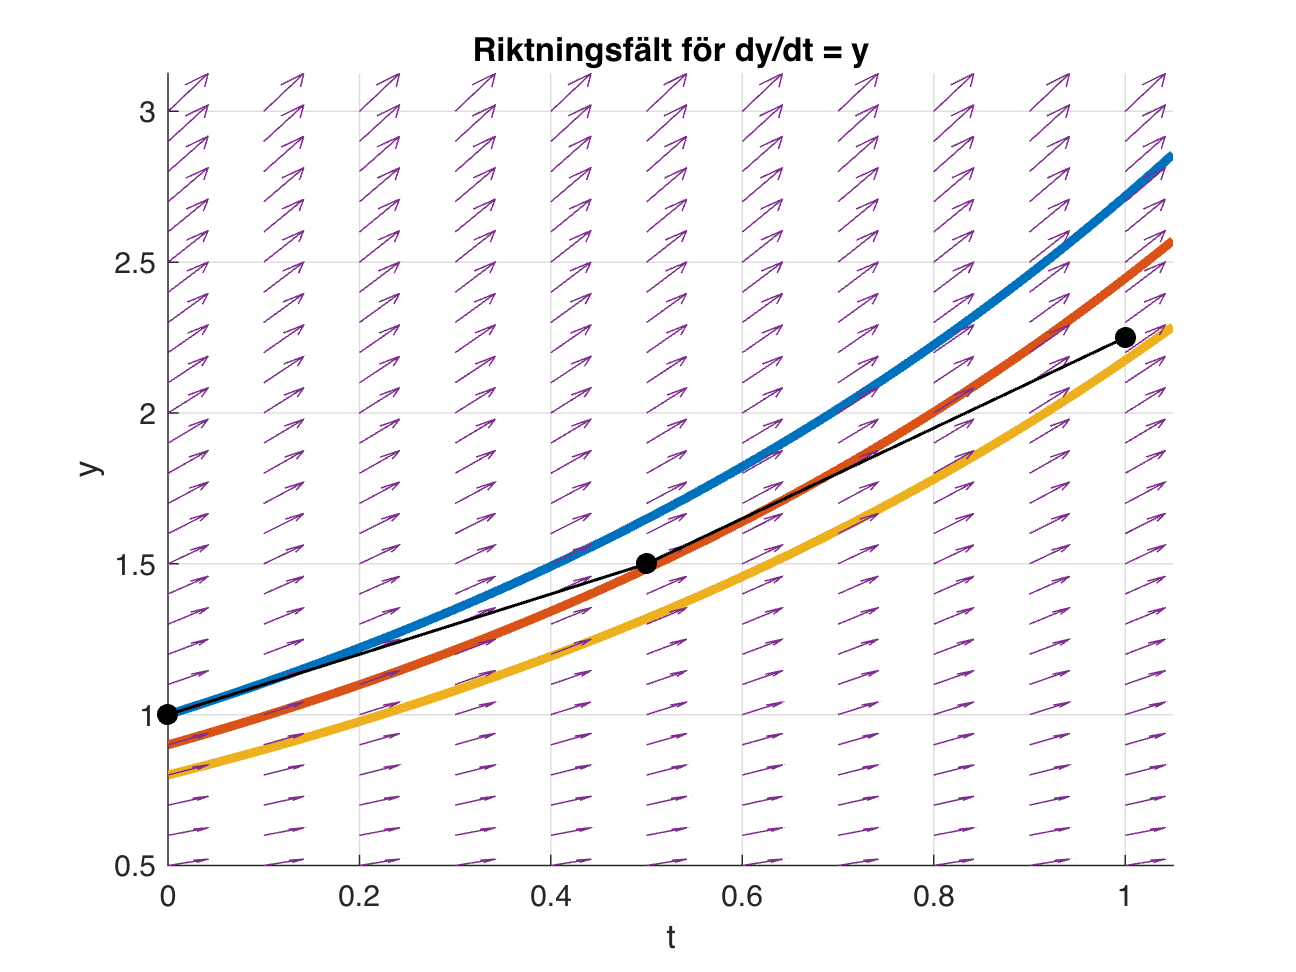

clf
hold on 
plot(t,y1,'LineWidth',3)

grid on
plot(t,y2,'LineWidth',3)
plot(t,y3,'LineWidth',3)
ylim([0.5,3])

[T, Y] = meshgrid(0:0.1:1, 0.5:0.1:3);
%S = -T+ Y + 1./Y-T;
S = Y;
quiver(T, Y, ones(size(S)), S,1)
axis tight; xlabel('t'), ylabel('y')
title('Riktningsfält för dy/dt = y')

[te,ye]  = odeEuler(@funkEx1,[0,1],1,2);
plot(te,ye,'k-o','LineWidth',1,'MarkerFaceColor','k')
hold off

## Ex 14.2 Jönsson

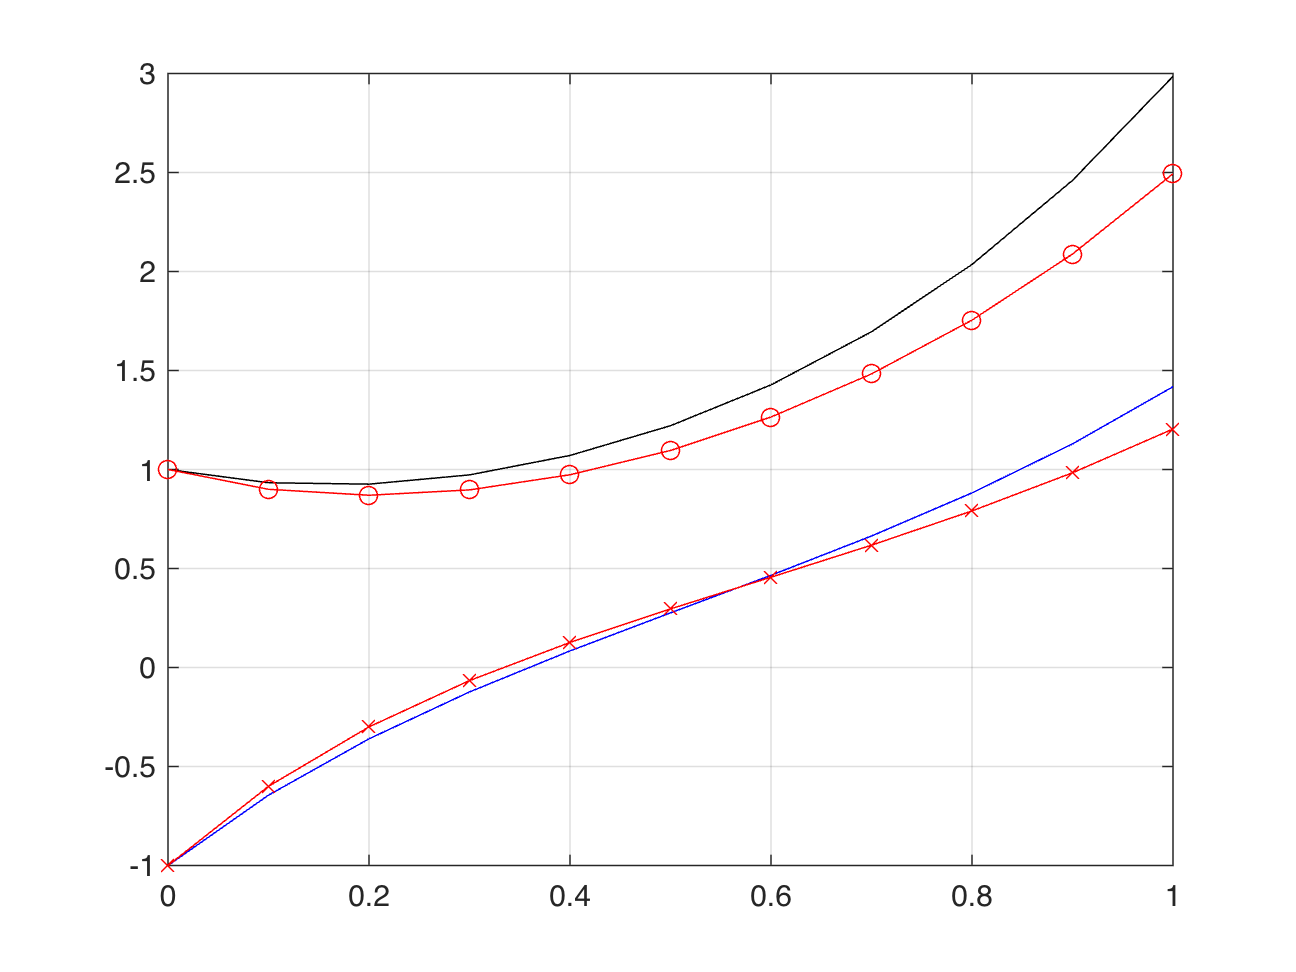

clear 
tspan = [0; 1];
y1 = [1;-1];
n = 10;
[t,y] = odeEulerNY(@funkEx142,tspan,y1,n);

% Analytisk lösning
c1 = 1/5;
c2 = 3/5;
Y= c1*[2;1]*exp(2*t) + c2*[1;-2]*exp(-3*t);
clf
plot(t,Y(1,:),'k')
hold on, grid on
plot(t,y(1,:),'r-o')
plot(t,Y(2,:),'b')
plot(t,y(2,:),'r-x')
hold off

## Ex 14.3 Jönsson

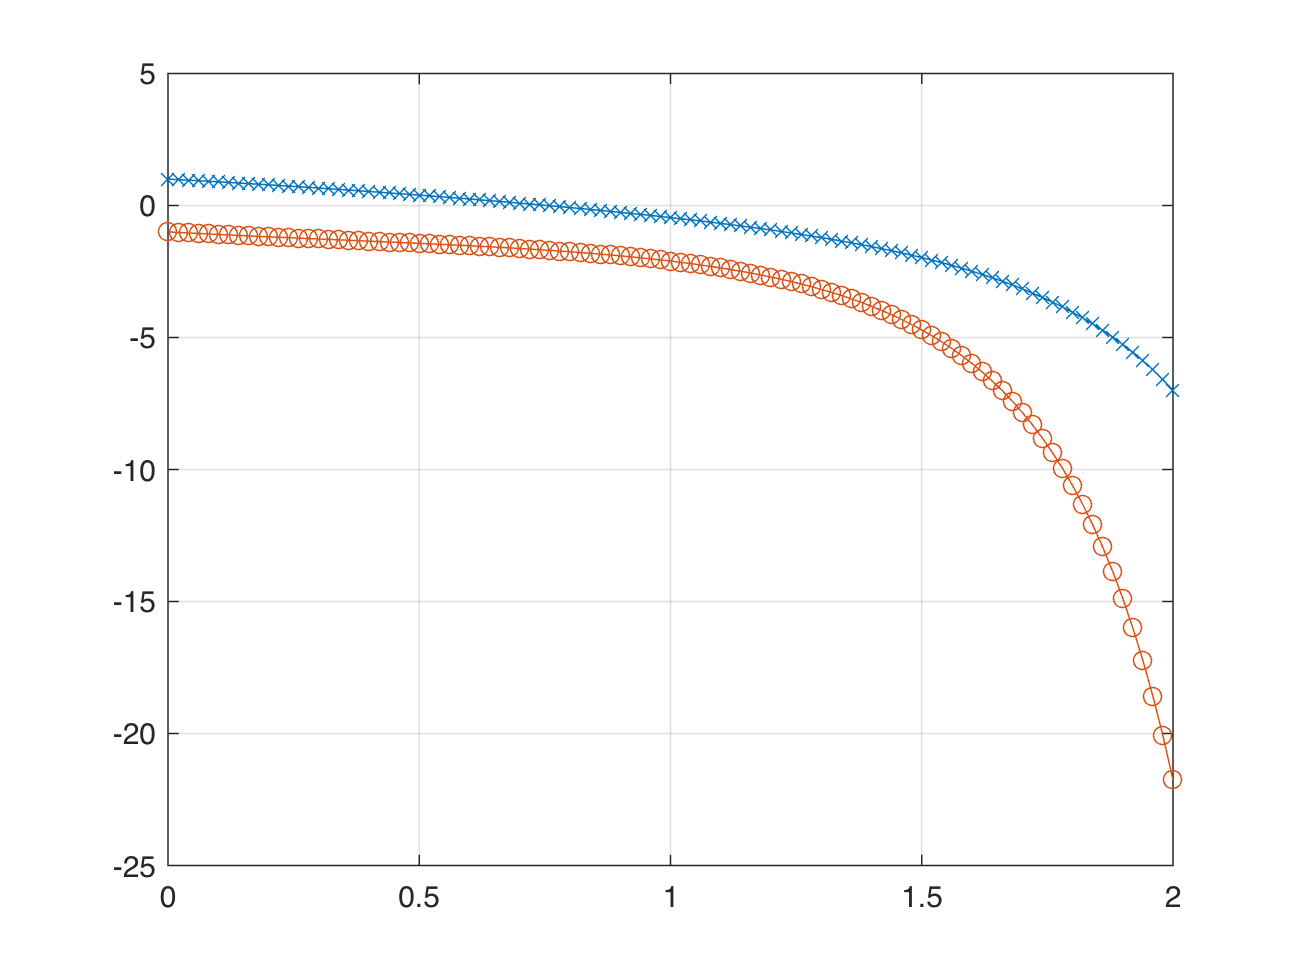

%Ex: 14.3a
clear
%funkEx143a(1,[1.3; 3])
tspan = [0,2];
ybv = [1; -1];
n = 100;

[t,y] = odeEulerNY(@funkEx143a,tspan,ybv,n);

clf
plot(t,y(1,:),'-x')
hold on
plot(t,y(2,:),'-o')
grid on
hold off

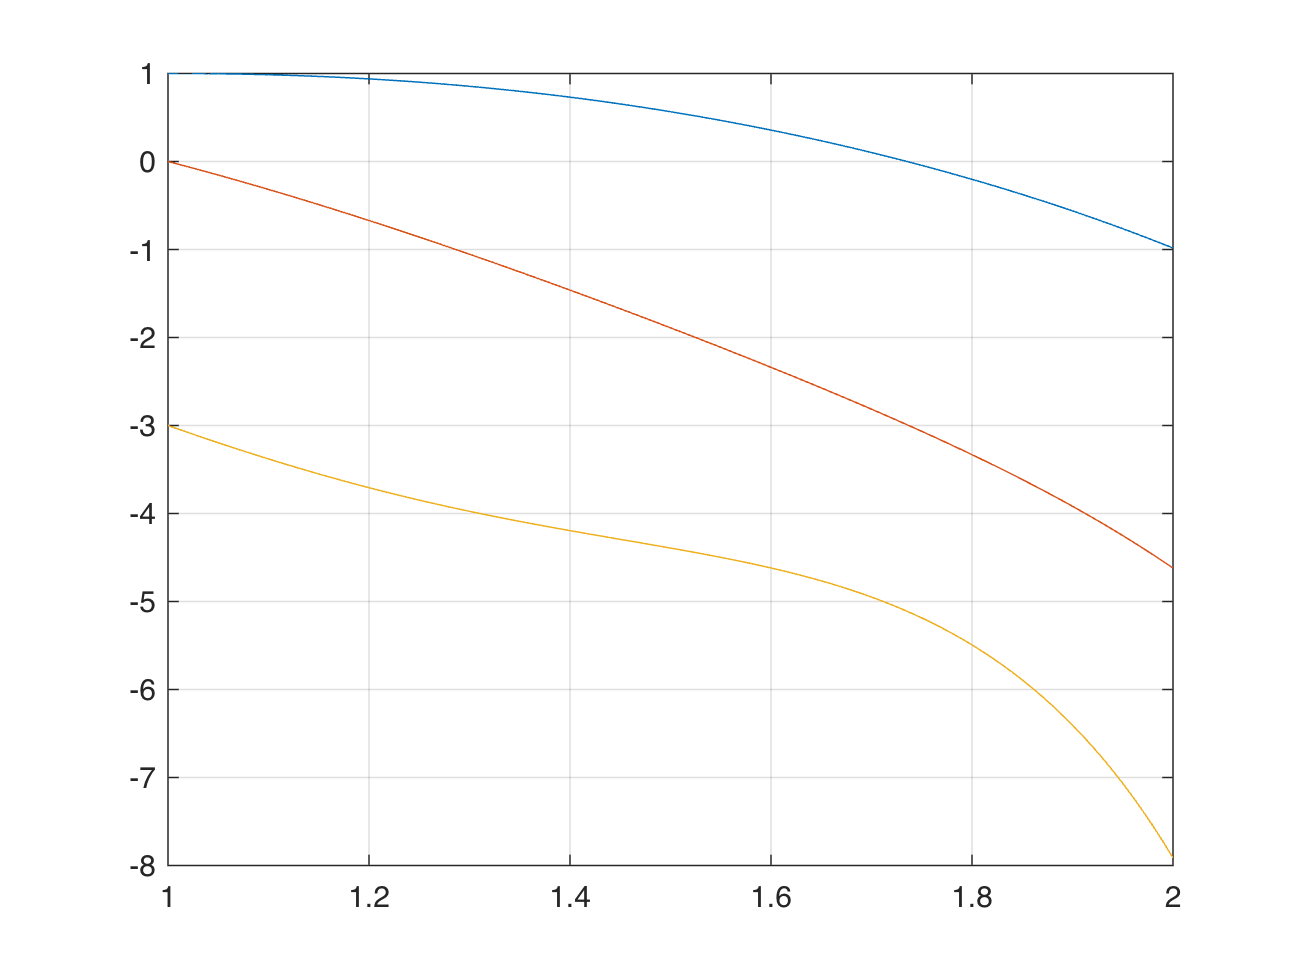

% Ex 14.3b
clear
ybv = [1;0;-3];
tspan = [1,2];
n = 100;

[t,y] = odeEulerNY(@funkEx143b,tspan,ybv,n);
plot(t,y(1,:))
hold on
plot(t,y(2,:))
plot(t,y(3,:))
grid on
hold off

## MATLABs ODE-lösare (ode45)

Ex: y' = y

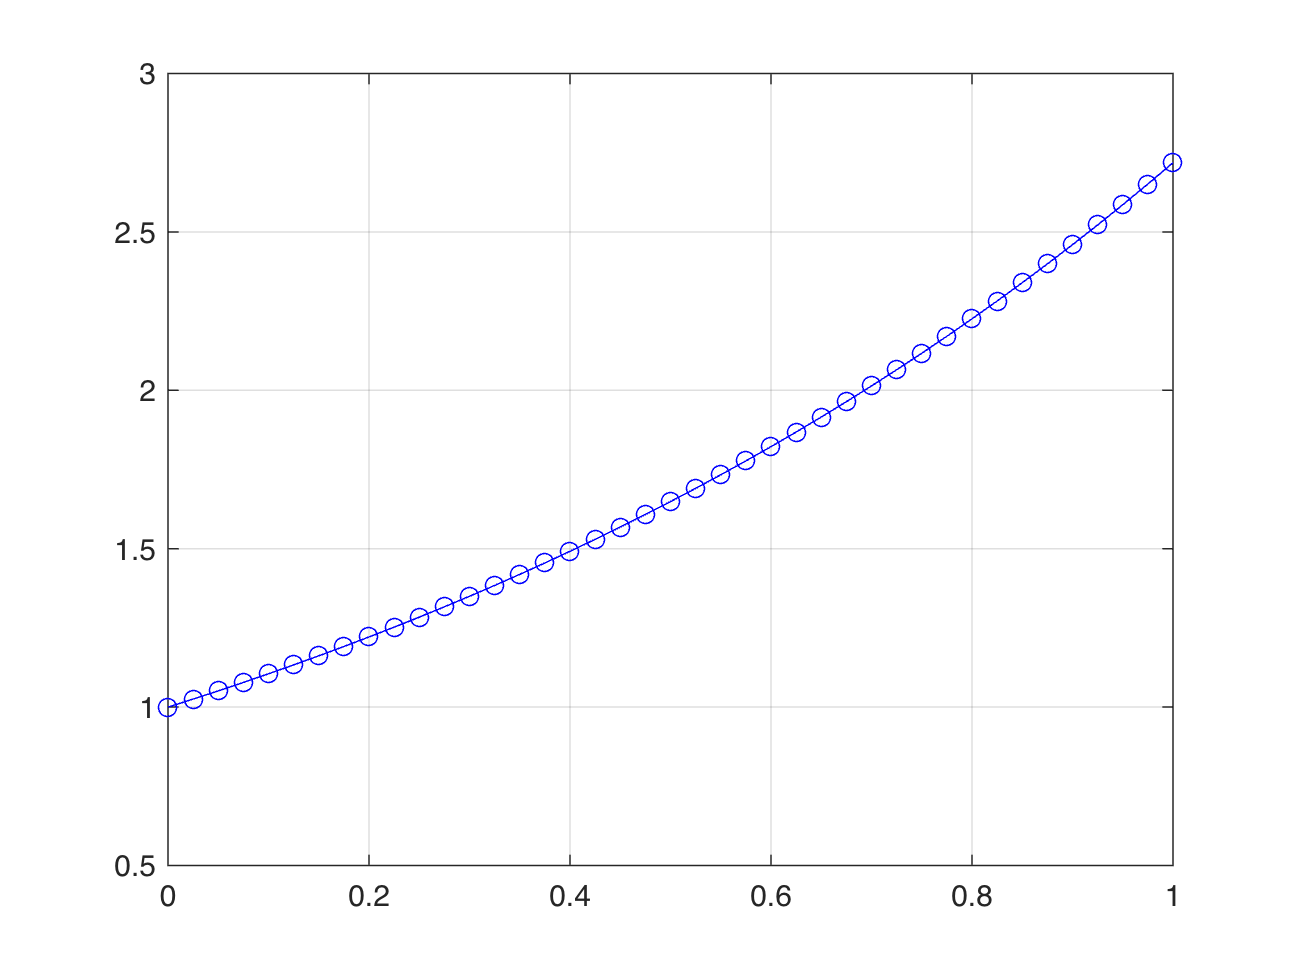

clear
tspan = [0, 1];
y1 = 1;

[t,y]  = ode45(@funkEx1,tspan,y1);
clf
plot(t,y,'b-o' )
ylim([0.5,3])
grid on

## Ex: funcBruss.m

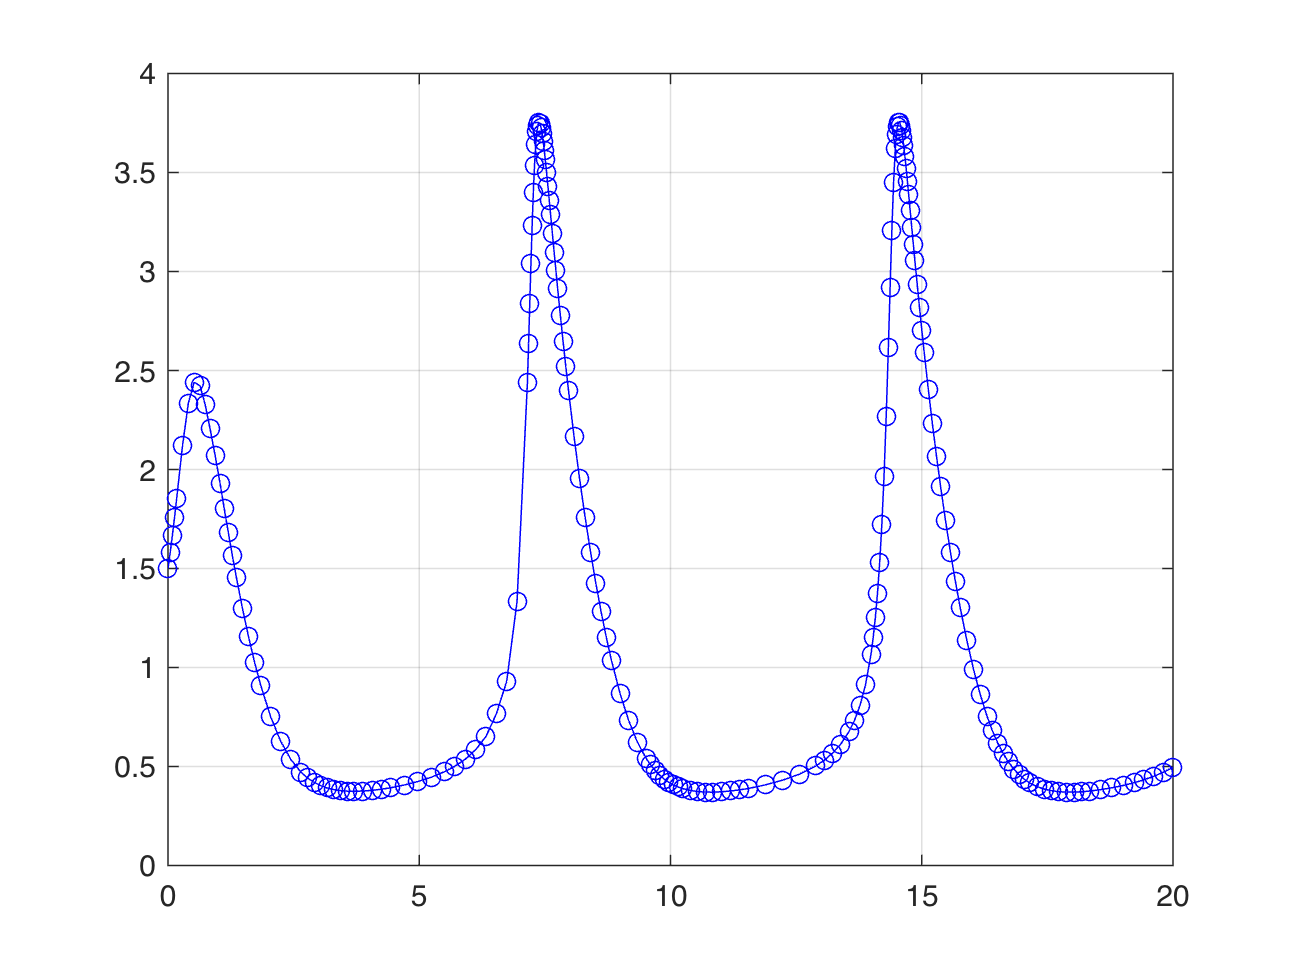

clear 
tspan = [0, 20];
y1 = [1.5; 3];

[t,y]  = ode45(@funcBruss,tspan,y1);
clf
plot(t,y(:,1),'b-o' )
grid on

## ode45 bestämmer själv steglängderna

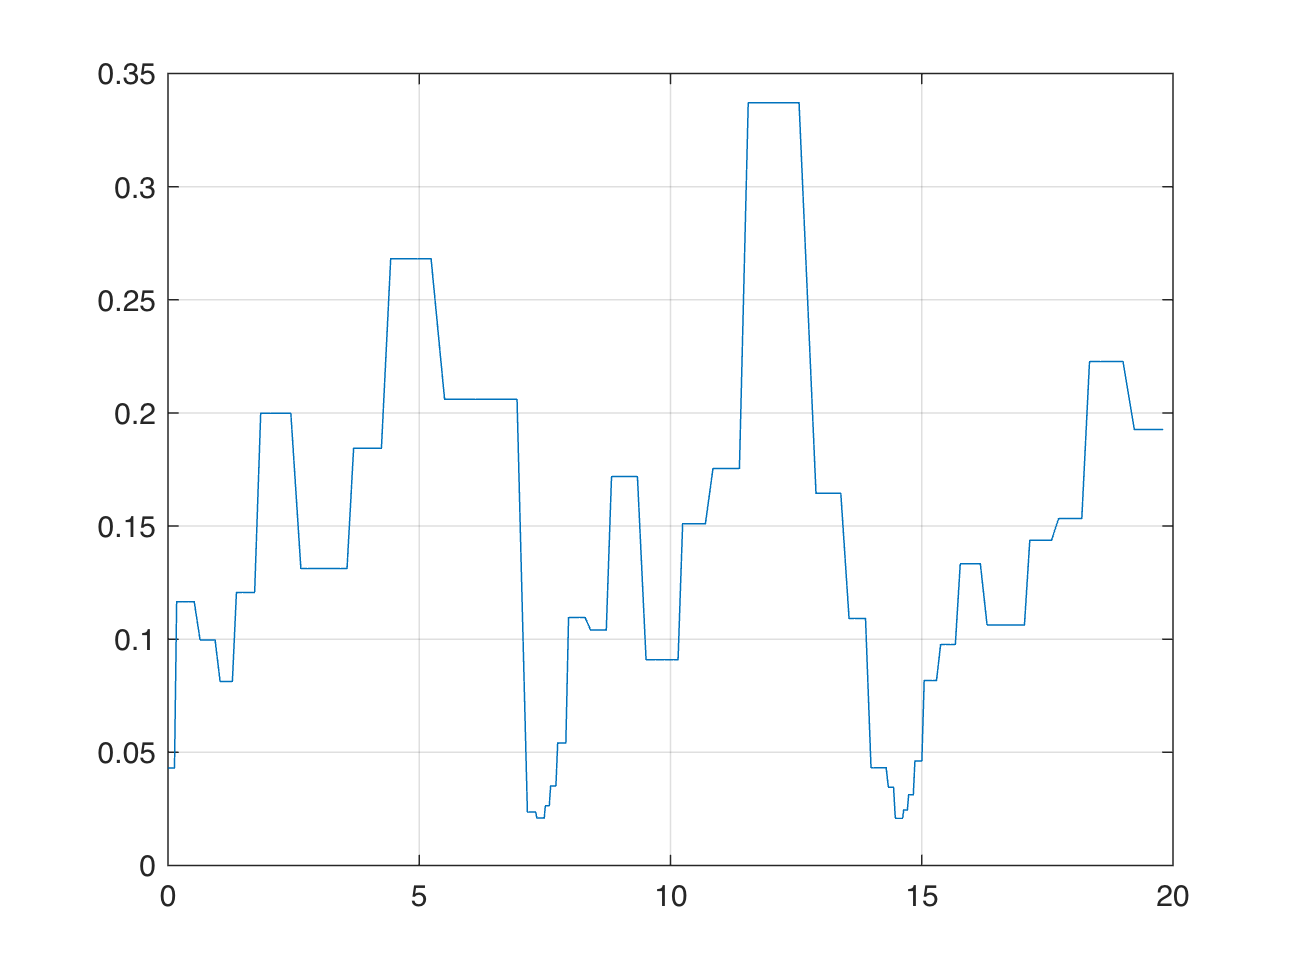

clf; plot(t(1:end-1),t(2:end)-t(1:end-1)); grid on

## Låt ODE45 returnera lösningen i bestämda tidpunkter

clear
tspan = [0, 20];
ybv = [1.5; 3];

n = 100;
t = linspace(tspan(1),tspan(2),n+1);
[t1,y1]  = ode45(@funcBruss,tspan,ybv);
[t2,y2]  = ode45(@funcBruss,t,ybv);

clf
plot(t1,y1(:,1),'b-o' )
%hold on
%plot(t2,y2(:,1),'r-x' )
grid on
hold off